clear
clc
close all

%% =====================================================
% 1 LOAD DATASET
%% =====================================================

data = readtable("C:\Users\arigi\Downloads\Testing.csv");


% Make names valid
data.Properties.VariableNames = matlab.lang.makeValidName(data.Properties.VariableNames);

vars = data.Properties.VariableNames;

disp("===== COLUMN NAMES =====")

===== COLUMN NAMES =====


disp(vars')

    {'TripId'                          }
    {'Time_s_'                         }
    {'Velocity_km_h_'                  }
    {'Elevation_m_'                    }
    {'Throttle___'                     }
    {'MotorTorque_Nm_'                 }
    {'LongitudinalAcceleration_m_s_2_' }
    {'RegenerativeBrakingSignal'       }
    {'BatteryVoltage_V_'               }
    {'BatteryCurrent_A_'               }
    {'BatteryTemperature__C_'          }
    {'max_BatteryTemperature__C_'      }
    {'SoC___'                          }
    {'displayedSoC___'                 }
    {'min_SoC___'                      }
    {'max_SoC___'                      }
    {'HeatingPowerCAN_kW_'             }
    {'HeatingPowerLIN_W_'              }
    {'RequestedHeatingPower_W_'        }
    {'AirConPower_kW_'                 }
    {'HeaterSignal'                    }
    {'HeaterVoltage_V_'                }
    {'HeaterCurrent_A_'                }
    {'AmbientTemperature__C_'          }
    {'CoolantTem


%% =====================================================
% 2 SAFE COLUMN FINDER (IMPORTANT)
%% =====================================================

% Function: returns EXACTLY ONE column index
findCol = @(pattern) find(contains(vars, pattern, 'IgnoreCase', true),1);

% Extract safely
Velocity    = data{:, findCol('Velocity')};
Elevation   = data{:, findCol('Elevation')};
Throttle    = data{:, findCol('Throttle')};
Torque      = data{:, findCol('MotorTorque')};

Acceleration = data{:, findCol('LongitudinalAcceleration')};
Regen        = data{:, findCol('RegenerativeBraking')};

Voltage     = data{:, findCol('BatteryVoltage')};
Current     = data{:, findCol('BatteryCurrent')};

BatteryTemp = data{:, findCol('BatteryTemperature_C_')}; % avoids max temp
AmbientTemp = data{:, findCol('AmbientTemperature')};

AirCon      = data{:, findCol('AirConPower')};
Heater      = data{:, findCol('HeaterCurrent')};

SOC         = data{:, findCol('SoC_')}; % ensures main SoC only

%% =====================================================
% 3 FEATURE MATRIX
%% =====================================================

X = [Velocity Elevation Throttle Torque Acceleration Regen ...
     Voltage Current BatteryTemp AmbientTemp AirCon Heater];

Y = SOC;

%% =====================================================
% 4 CLEAN DATA
%% =====================================================

validIdx = all(~isnan(X),2) & ~isnan(Y) & all(~isinf(X),2);

X = X(validIdx,:);
Y = Y(validIdx);

%% =====================================================
% 5 TRAIN TEST SPLIT
%% =====================================================

cv = cvpartition(length(Y),'HoldOut',0.3);

Xtrain = X(training(cv),:);
Ytrain = Y(training(cv));

Xtest = X(test(cv),:);
Ytest = Y(test(cv));

%% =====================================================
% 6 RANDOM FOREST
%% =====================================================

model = fitrensemble(Xtrain,Ytrain,...
        'Method','Bag',...
        'NumLearningCycles',300,...
        'Learners','tree');

%% =====================================================
% 7 PREDICTION
%% =====================================================

SOC_pred = predict(model,Xtest);

%% =====================================================
% 8 METRICS
%% =====================================================

RMSE = sqrt(mean((Ytest - SOC_pred).^2));
MAE  = mean(abs(Ytest - SOC_pred));
R2   = 1 - sum((Ytest - SOC_pred).^2) / sum((Ytest - mean(Ytest)).^2);

fprintf('\n===== PERFORMANCE =====\n')


===== PERFORMANCE =====


fprintf('RMSE = %.4f\n', RMSE)

RMSE = 0.2264


fprintf('MAE  = %.4f\n', MAE)

MAE  = 0.1247


fprintf('R2   = %.4f\n', R2)

R2   = 0.9995


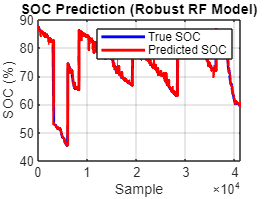


%% =====================================================
% 9 PLOT
%% =====================================================

figure
plot(Ytest,'b','LineWidth',2)
hold on
plot(SOC_pred,'r','LineWidth',2)

legend('True SOC','Predicted SOC')
xlabel('Sample')
ylabel('SOC (%)')
title('SOC Prediction (Robust RF Model)')
grid on

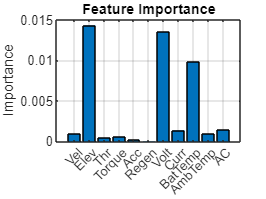


%% =====================================================
% 10 FEATURE IMPORTANCE
%% =====================================================

figure
imp = predictorImportance(model);

bar(imp)
title('Feature Importance')
ylabel('Importance')
xticklabels({'Vel','Elev','Thr','Torque','Acc','Regen',...
             'Volt','Curr','BatTemp','AmbTemp','AC','Heater'})
xtickangle(45)
grid on